car = DataLoader('car', 7, [1, 11]);

montage(car.image, BackgroundColor=[0.5 0.5 0.5], BorderSize=[5 5])

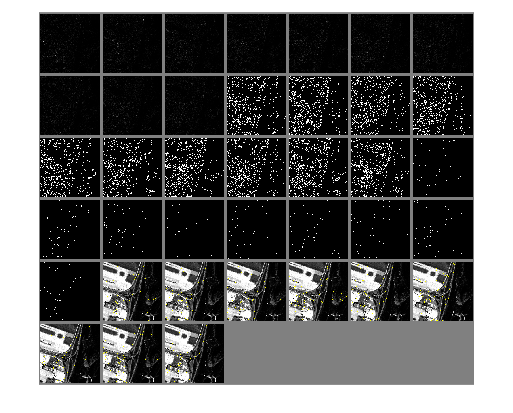

imgOverlays = {};
for i=1:(car.interval-2)
    imgOverlays{i}=imoverlay(car.image{i+1}, car.and_output{i}, 'yellow');
end

montage([car.diff car.outlier car.and_output, imgOverlays], ...
    BackgroundColor=[0.5 0.5 0.5], BorderSize=[5 5])

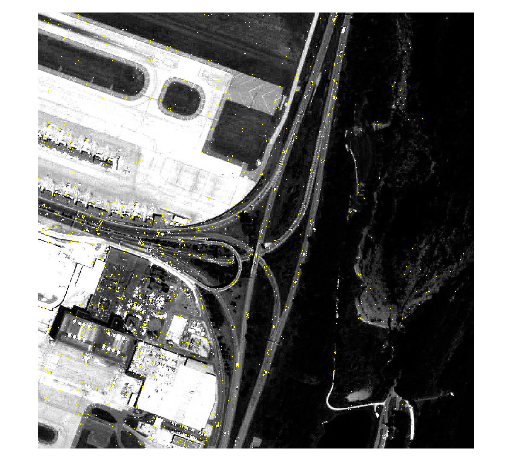

shape=insertShape(car.image{7},'rectangle',car.hblob_bbox{5}, 'Linewidth',1);
imshow(imgOverlays{5})

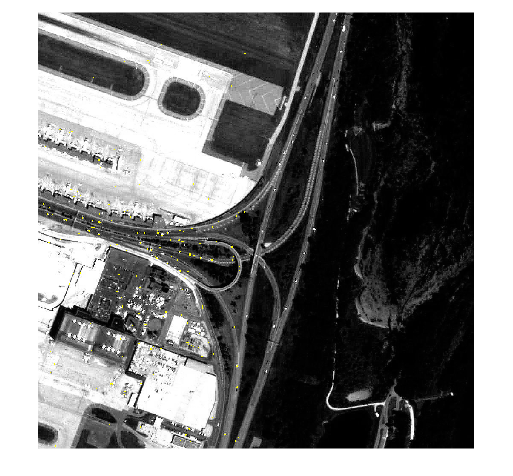

imshow(shape)